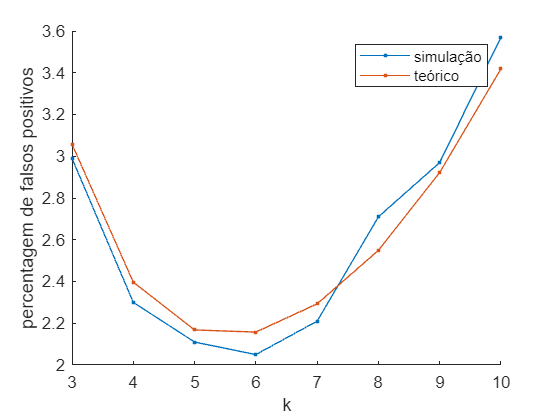

ficheiro=fopen("wordlist-preao-20201103.txt");
palavras=textscan(ficheiro,"%s",'delimiter','\n');
palavras=palavras{1};
fclose(ficheiro);
probsT = zeros(1,8);
probs = zeros(1,8);
j=1;
n=8000;
m=1000;
chaves=palavras(1:1000);
chaves2 = palavras(1001:11000);

for k=3:10

    falsos_positivos = 0;
    filtro=inicializarFiltro(n);
    
    for i=1:length(chaves)
        filtro=adicionarElemento(filtro,chaves{i},k);
    end

    for i= 1:length(chaves2)
        if pertenceConjunto(filtro,chaves2{i},k)
            falsos_positivos = falsos_positivos+1;
        end
    end

    fp = falsos_positivos/length(chaves2)*100;
    p = (1 - exp(-k*m/n))^k * 100;
    probsT(j) = p;
    probs(j) = fp;
    j = j + 1;
end

ks = 3:10;
hold on
simulacao = plot(ks,probs,'.-');
teorico = plot(ks,probsT,'.-');
legend([simulacao teorico],"simulação","teórico")
xlabel("k");
ylabel("percentagem de falsos positivos");
hold off

fprintf("K ótimo: %d; percentagem de falsos positivos: %.2f%%\n",ks(probs==min(probs)),min(probs));

K ótimo: 6; percentagem de falsos positivos: 2.05%
